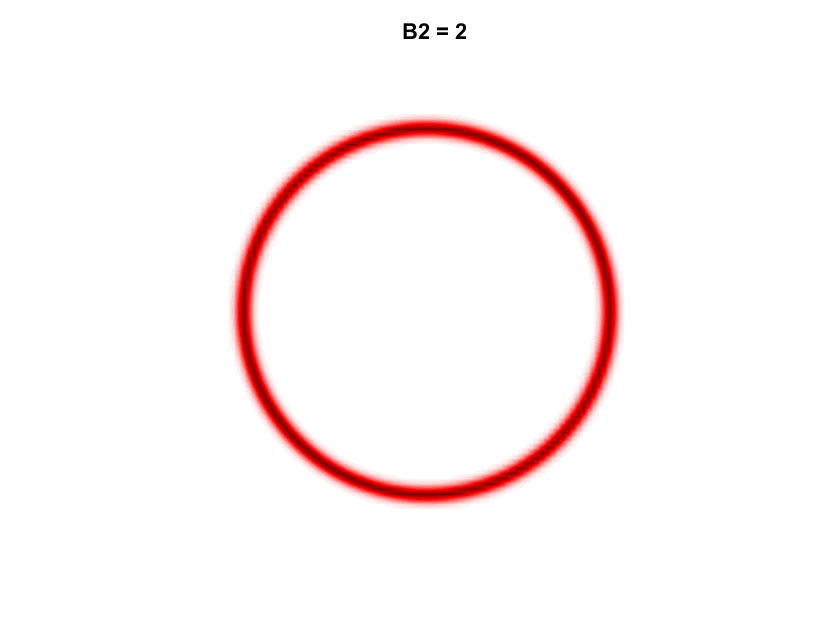

% This script was used experiment with how changing different values 
% in the ring generation alters the appearance of images, mostly for
% demonstration purposes.

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear

% 2D coordinate system
res = 96;  %try 256/512
x = linspace(-1,1,res);
[X, Y] = meshgrid(x);
R = sqrt(X.^2+Y.^2);

cos_theta = Y./R;

P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial
P4 = (1/8)*(35*cos_theta.^4 - 30*cos_theta.^2 + 3);     %fourth legendre polynomial
P6 = (1/16)*(231*cos_theta.^6 - 315*cos_theta.^4 - 105*cos_theta.^2 - 5);   %sixth legendre polynomial

%imnoise to sample
%imgaussfilt

% set coefficients
A0 = 1;   %amplitude
R0 = 0.75;  %radius
W0 = 0.03; %width

B2 = 0;   %beta-2 parameter set between -1 and 2
I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
showim(I,1)
title("B2 = 2")

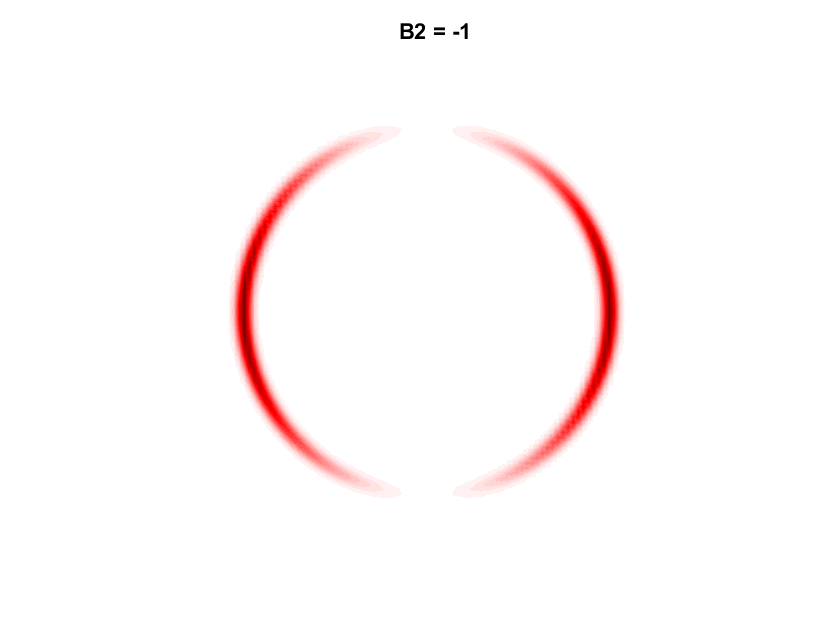


B2 = -1;
I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
showim(I,1)
title("B2 = -1")

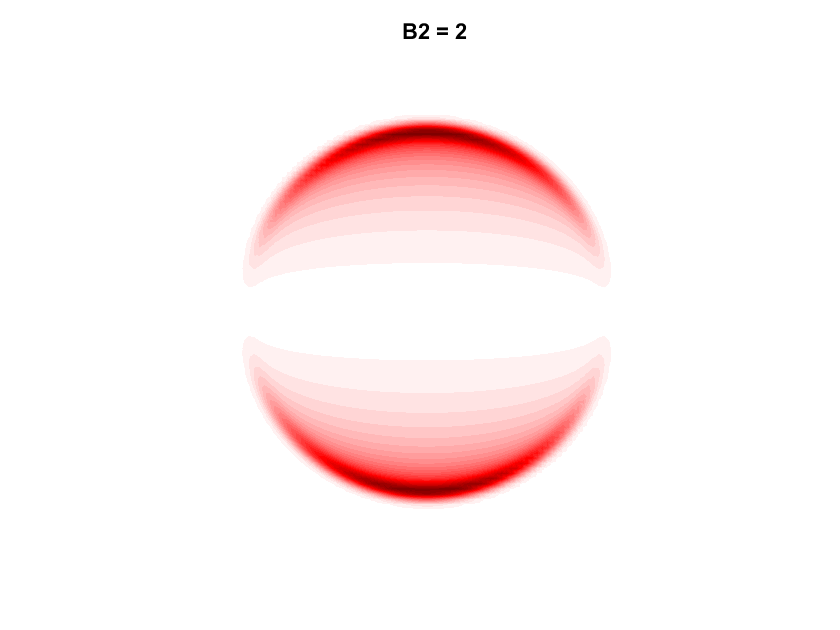



B2 = 2;   %beta-2 parameter set between -1 and 2
I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I = Abel(I);
showim(I,1)
title("B2 = 2")

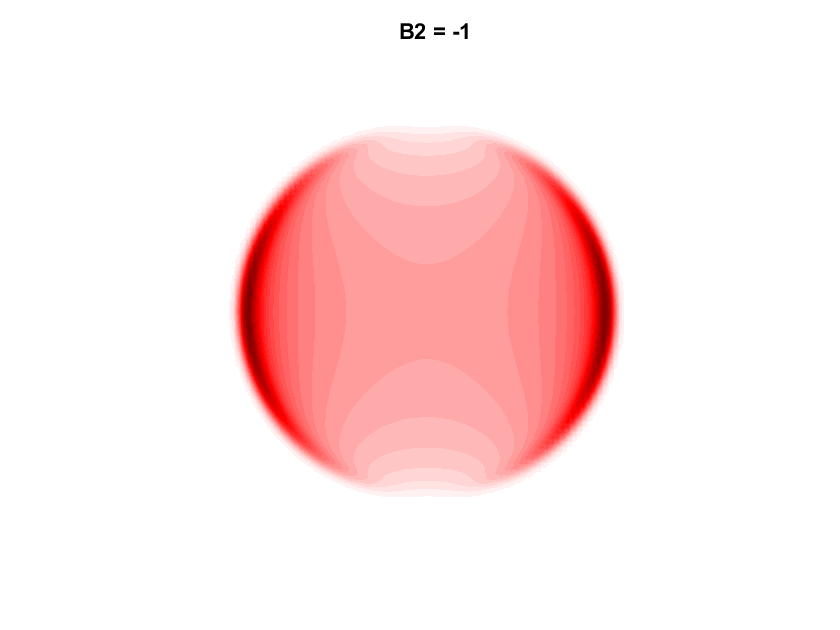


B2 = -1;
I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I = Abel(I);
showim(I,1)
title("B2 = -1")

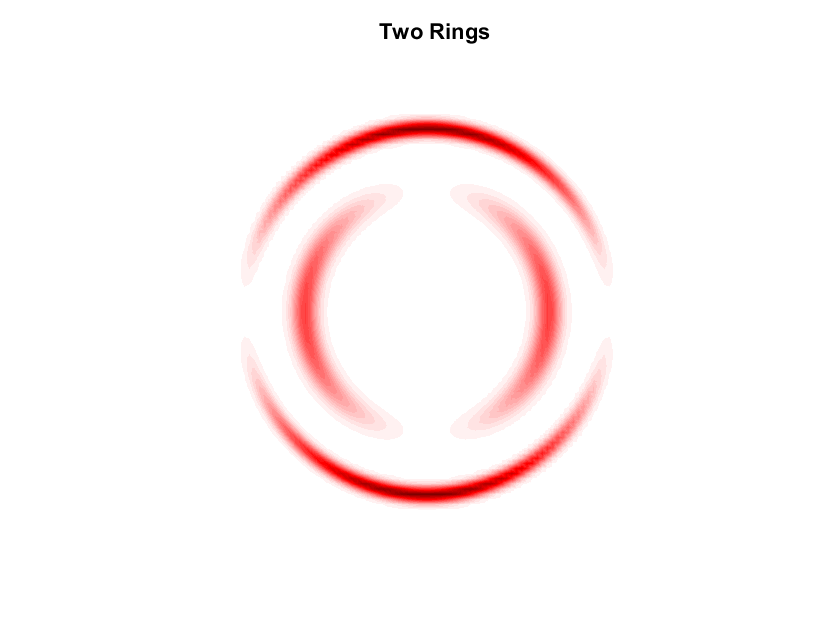


B2 = 2;
A0 = 1;
R0 = 0.75;
W0 = 0.03;
I1 = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
A0 = 1;
R0 = 0.5;
W0 = 0.05;
B2 = -1;
I2 = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I = I1 + I2;
showim(I,1)
title("Two Rings")

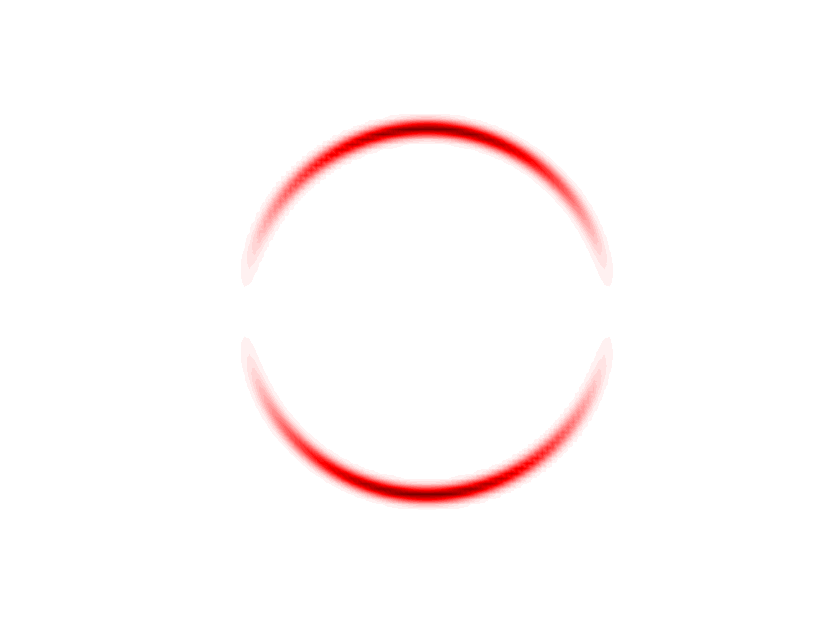

% shading flat

showim(I1, 1)

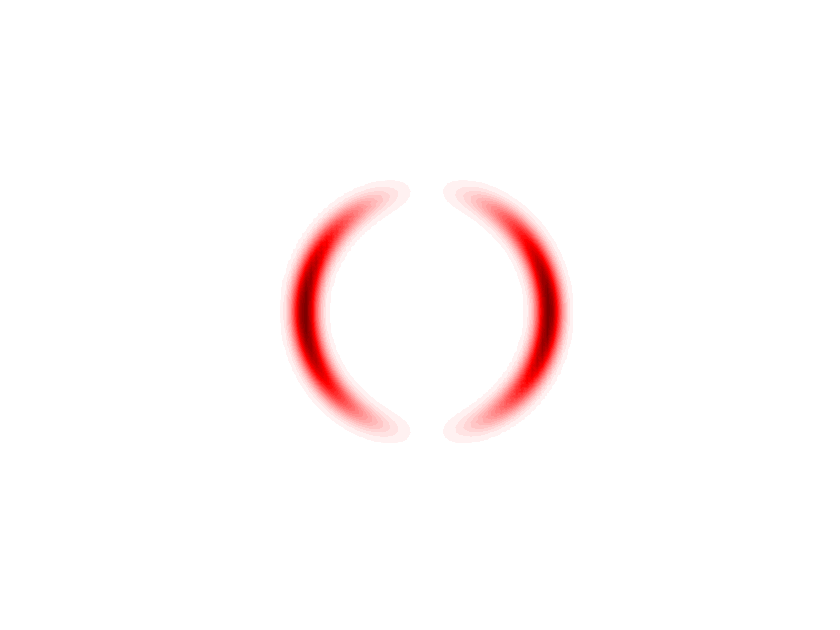

showim(I2, 1)

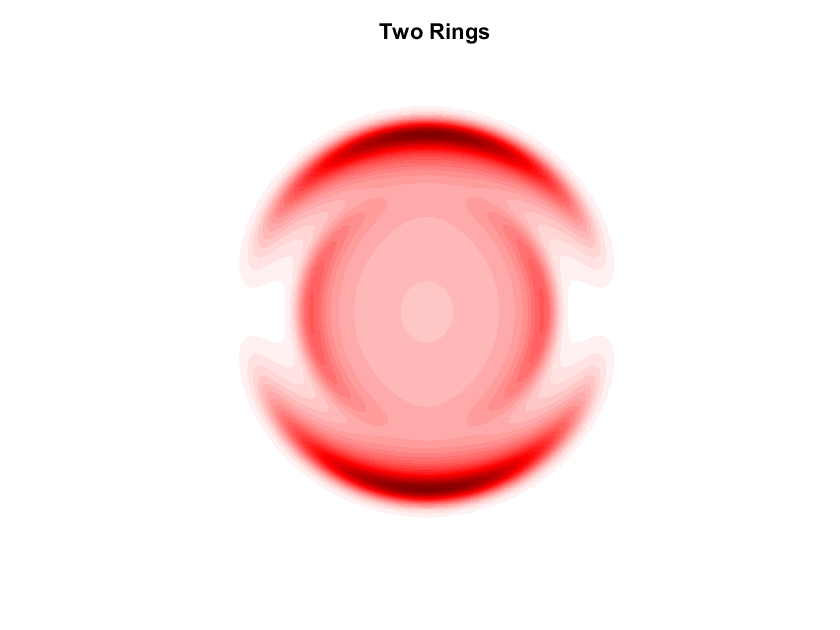



B2 = 2;
A0 = 1;  
R0 = 0.75;   %(0.8-0.5).*rand + 0.5
W0 = 0.05; 
I1 = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I1 = Abel(I1);

A0 = 1; %(0.7-0.4).*rand + 0.4
R0 = 0.5;
W0 = 0.05;
B2 = -1;
I2 = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I2 = Abel(I2);
I = I1 + I2;
% I = Abel(I);          %ask - do I Abel individually, or together? DOESNT'
% MATTER!
showim(I,1)
title("Two Rings")

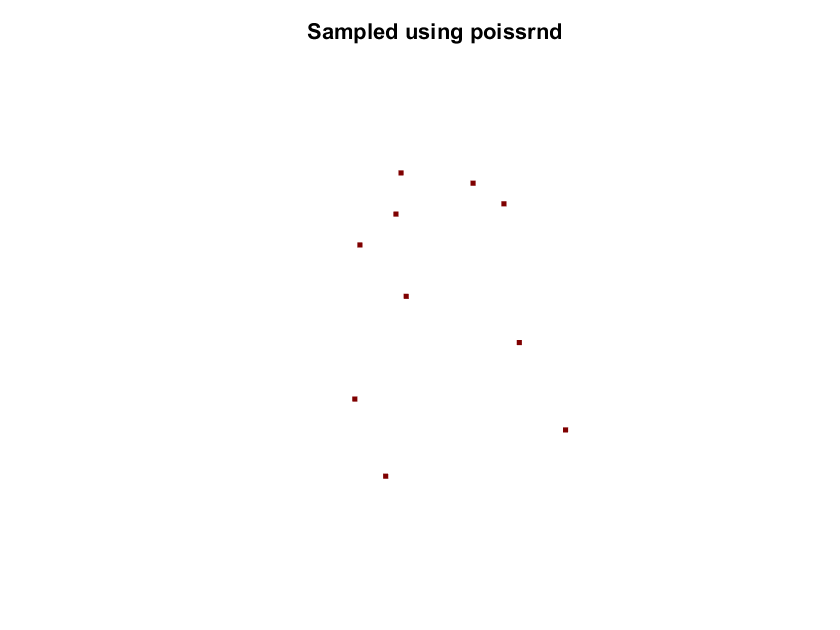

% shading flat


% %sampled using imnoise
% A0 = 0.75;   %amplitude
% R0 = 0.75;  %radius
% W0 = 0.05; %width
% I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
% I = I*10e-13;
% I_noisy = imnoise(I, 'poisson');
% showim(I_noisy,1)
% title("Sampled using imnoise")
% nnz(I_noisy)
% %try to deconvolve noise filter?


%sampled using my own code
% I = A0*exp(-((R-R0)/W0).^2).*(1 + B2*P2);
I = Abel(I);
I = I/sum(I, 'all');
counts = I*10^1;   %put to 10^3 
I = poissrnd(counts, height(I), length(I));
showim(I,1)
shading flat
title("Sampled using poissrnd")

count = sum(I, 'all')

count = 10

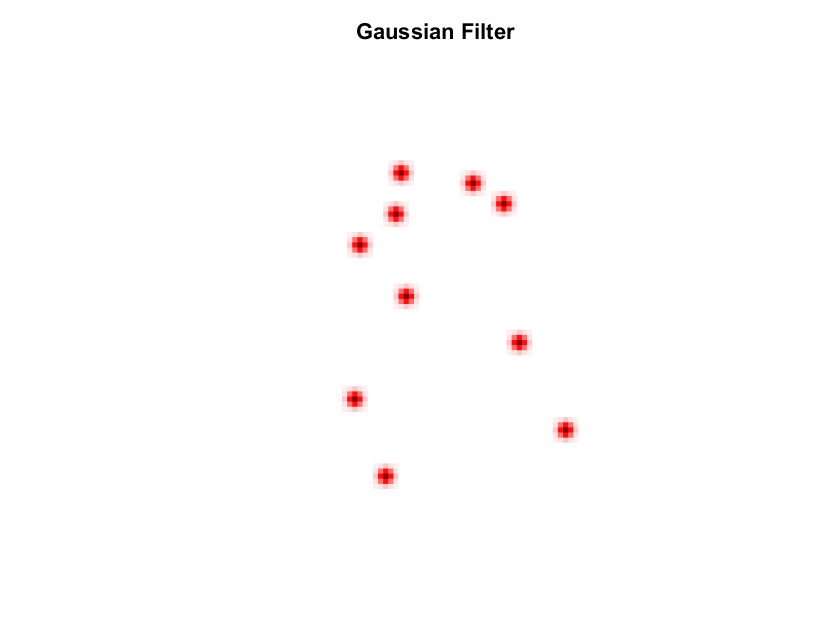



%gaussian filter
sigma = 1;  %higher sigma broadens but lower intensity
I = imgaussfilt(I,sigma);

showim(I,1)
shading flat
title("Gaussian Filter")




%integrate
%test neural net
